# Signal Processing Basics

Instructions are in the task pane to the left. Complete and submit each task one at a time.

## Task 1

This course uses a clip from a humpback whale recording from the Monterey Bay Aquarium Research Institute. You can find the sound used in this lesson [here](https://freesound.org/people/MBARI_MARS/sounds/498708/).

You can import audio files into MATLAB. The signal data and the sample rate are stored in separate variables.

`[``sig``,``fs``]` `=` `audioread``(``"``filename``"``)`

[whale, fs] = audioread("./data/mbari-mars.wav");

## Task 2

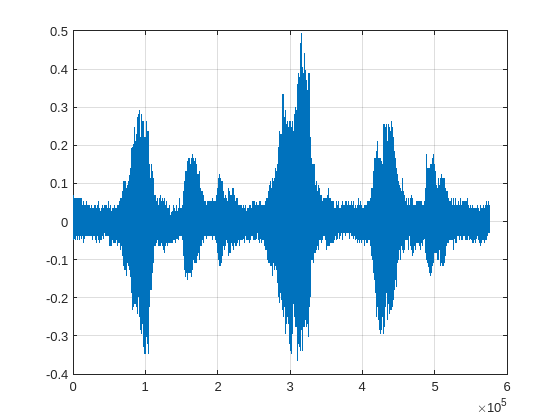

plot(whale)
grid on

## Task 3

To view the frequency content of a signal, you can calculate the power spectrum with the `pspectrum` function.

`pspectrum``(``mysig``,``fs``)`

If you don't use any output arguments, `pspectrum` creates a plot.

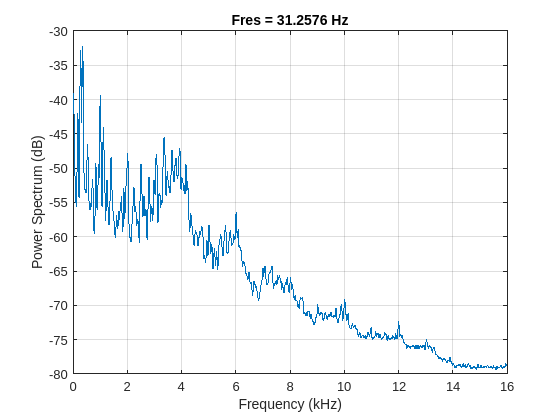

pspectrum(whale, fs)

## Task 4

You can also create a spectrogram with the `pspectrum` function by including the input `"spectrogram"`.

`pspectrum``(``mysig``,``fs``,``"spectrogram"``)`

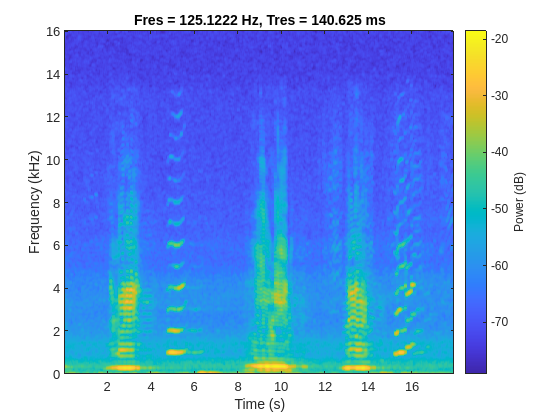

pspectrum(whale, fs, "spectrogram")

## Task 5

You can lowpass filter with the `lowpass` function.

`lowpass``(``mysig``,``pass``,``fs``)`

If you don't use any output arguments, `lowpass` creates a plot.

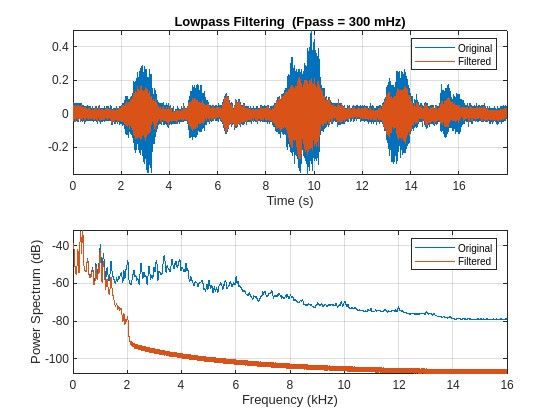

lowpass(whale, 0.3, fs)

## Task 6

With `pspectrum` and filtering functions like `lowpass`, you can use output arguments to save the result to a variable. Then you can perform further processing or customize the visualizations.

whalefilt = lowpass(whale, 0.3, fs)

whalefilt =     0.0103
    0.0129
    0.0156
    0.0183
    0.0211
    0.0237
    0.0261
    0.0282
    0.0301
    0.0315
